%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%  EC516 Project 01  %%%
%%% Jeremiah Sullivan  %%%
%%%    ML, IC, or RL   %%%
%%%   November 2018    %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Project Requirements
% (a)	Record and display a speech signal
% (b)	(3 points) Compute and display the discrete TDFT of the
%           rectangular	(“box”)	window, duration ~20 ms
% (c)	(4 points) Use GFBS Method to compute signal back from discrete TDFT
clc; clear all; close all;
set(groot,'defaultfigureposition',[400 250 500 250]); % Reduce figure sizes


## A: Generate and display signal

Using Macbook or Dell as recording platforms, with Bose Headphones as transducer. More noise has been seen on the Dell, but that machine is also plugged into AC power. Clear anti-aliasing filters are visible above 10 kHz on the Dell.

Initial trials were completed in a noisy coffeeshop (update this if location changes).

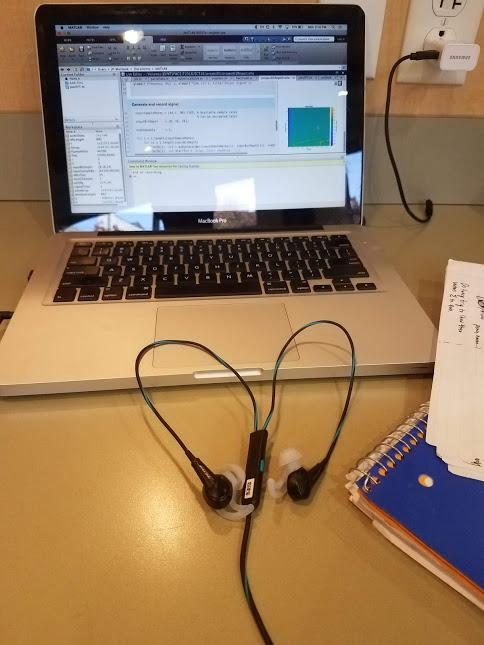

For replicability, let's also generate some sound. Let's try an LFM chirp. We now have further unkowns (internal afg / transmit chain). 

Max audio-settings, 24-bit, 96 kHz... This seems unnecessary.

fSampleOut = 44.1E3;
signalTime = 1; % second
fVec       = [1000, 4000]; % from 100 Hz to 4 kHz
timeArray  = 0:(1/fSampleOut):signalTime; % Time (seconds)
fArray     = linspace(fVec(1), fVec(2), length(timeArray) );
nBitsOut   = 24;
y          = chirp(timeArray, fVec(1), timeArray(end), fVec(end));

Generate and check output signal

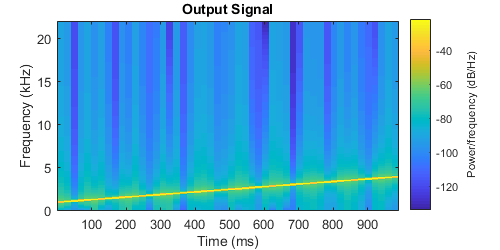

windowLength = 20E-3.*fSampleOut;
dftLength = windowLength;
spectrogram(y, windowLength, round(0.01*windowLength), dftLength, fSampleOut, 'yaxis')
title('Output Signal');

## Generate and record signal

inputSampleRates = 48E3; %44.1, 96.*1E3; % Available sample rates
inputBitDepth    = 24;
numChannels      = 1;
recObj = audiorecorder(inputSampleRates, inputBitDepth, numChannels);
recordTime = 3;
record(recObj, recordTime); % Record for 3 seconds
tic;
while toc < recordTime      % Generate a signal for 2 seconds
    sound(y, fSampleOut); pause(signalTime) ;
end
audioData = getaudiodata(recObj);

## Signal Processing on Recorded signal

y = audioData;
windowLength = 20E-3.*inputSampleRates;
unitWindow   = ones(windowLength, 1);
dftLength    = windowLength;

The following spectrograms compare the overlap (L) and window properties

- Hamming vs unit-step

- Full overlap (L=1) vs. no overlap

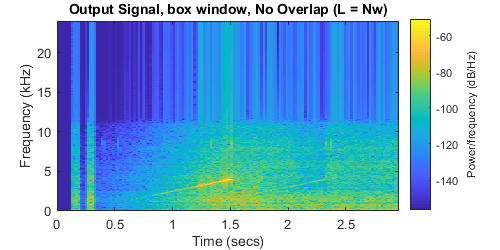

[fbs.UnitStep.s, fbs.UnitStep.w.fbs, fbs.UnitStep.t] =  ...
    spectrogram(y, unitWindow, windowLength-1, dftLength, inputSampleRates(1), 'twosided', 'yaxis');

figure;
[gfbs.UnitStep.s, gfbs.UnitStep.w.fbs, gfbs.UnitStep.t] =  ... % For analysis
    spectrogram(y, unitWindow, 0, dftLength, inputSampleRates(1), 'twosided','yaxis'); 

spectrogram(y, unitWindow, 0, dftLength, inputSampleRates(1), 'yaxis'); % For plot
%ylabel('Frequency (Hz)'); xlabel('Time (s)');
title('Output Signal, box window, No Overlap (L = Nw)');

We observe more frequency blurring with the unit step (sharp increases at the start of signal). 

We observe a smoother signal with more overlap (computing fft for every point). 

## Implimenting GFBS Method

First, we must verify the GFBS conditions are satisfied. 

L is defined by window overlap...

Number of overlapped samples, specified as a positive integer.

- If [`window`](https://www.mathworks.com/help/signal/ref/spectrogram.html#bultmx7-window) is scalar, then `noverlap` must be smaller than `window`.

- If `window` is a vector, then `noverlap` must be smaller than the length of `window`.

M is defined by the DFT length. We have purposefully set these parameters equal so that we have critical sampling in at least one case. 

The critically sampled case / unit step makes it very simple to reconstruct using f[n] = 1/w[n] = w[n]

j = sqrt(-1);
[M, L]  = size(gfbs.UnitStep.s);
Nw      = M; % Critically sampled

exponentialPart = @(k) (exp(j.*(2.*pi.*(k-1)./M) .* (0:(Nw-1)) ) );

temp    = zeros(1,M);
tempNew = zeros(1,M);
slow    = zeros(1, length(y));
tic;
for ll = 1:floor(length(y)/windowLength)
    indices = ((ll-1)*windowLength+1):((ll)*windowLength) ;
    temp    = zeros(1,M);     % Things breaks when I remove these
    tempNew = zeros(1,M);     % Things breaks when I remove these
    for k = 1:(M)             % Matlab arrays...
        tempNew = (gfbs.UnitStep.s(k,ll).* exponentialPart(k) );
        temp    = temp+tempNew;
        tempNew = zeros(1,M); % Things breaks when I remove these 
    end
    slow(indices) = temp;
end
result.slow.time = toc;
%-----------------------------------------------------------------------------%
ifftOut = zeros(1,M); tic;
for ll = 1:floor(length(y)/windowLength)
    indices = ((ll-1)*windowLength+1):((ll)*windowLength) ;
    temp = ifft(gfbs.UnitStep.s(:,ll), [], 1, 'symmetric');
    ifftOut(indices) = temp;
end
result.fast.time = toc;

result.fast.y = ifftOut; % (1./M)
result.slow.y = (1./M).* slow;
result.Fs   = inputSampleRates(1);
fprintf('Using fft takes: %01.1f milliseconds', result.fast.time*1E3)

Using fft takes: 78.2 milliseconds

fprintf('Using explicit method takes: %01.1f seconds', result.slow.time)

Using explicit method takes: 16.2 seconds

fprintf(['\nApprox %01.1f times faster, algorithmically expect about (M^2 / Mlog2M)  ~  %01.0f\n',...
         'I bet specifying "single-sided in ifft makes up for ~ 2 times faster\n'],...
        result.slow.time/result.fast.time, M/(log2(M))); 


Approx 207.6 times faster, algorithmically expect about (M^2 / Mlog2M)  ~  97
I bet specifying "single-sided in ifft makes up for ~ 2 times faster


## Analyze Results

imagRoundOff = log10([rms(real(result.fast.y)), rms(real(result.slow.y))]./ ...
    [rms(imag(result.fast.y)), rms(imag(result.slow.y))]);
% This test seems kind of hand-wavy
fprintf('Real component is %01.1f, %01.1f (fft, explicit) orders of magnitude above imaginary',...
         imagRoundOff(1), imagRoundOff(2));

Real component is Inf, 12.8 (fft, explicit) orders of magnitude above imaginary

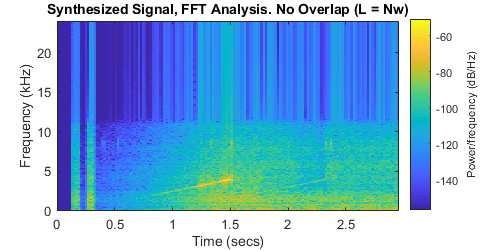

if imagRoundOff < 10
    disp('Signal may not be real (Synthesis algorithm is incorrect)');
end
spectrogram(real(result.fast.y), unitWindow, 0, dftLength, inputSampleRates(1), 'onesided','yaxis');
title('Synthesized Signal, FFT Analysis. No Overlap (L = Nw)');

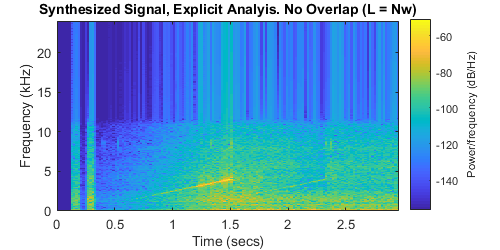

spectrogram(real(result.slow.y), unitWindow, 0, dftLength, inputSampleRates, 'onesided','yaxis');
title('Synthesized Signal, Explicit Analyis. No Overlap (L = Nw)');

Compare synthesized signal spectrogram w/ Box Window. Appear identical. Also sound identical. 